## **Visualisation des différentes configurations du robot**

### **Definition des variables**

% Définir les symboles pour les angles d'articulation
syms theta1 theta2 theta3 theta4;

% Définir les longueurs des bras
a1 = 2; % Longueur du premier bras
a2 = 3; % Longueur du deuxième bras
a3 = 2; % Longueur du troisième bras
a4 = 2; % Longueur du troisième bras
a5 = 2; % Longueur du troisième bras

% Définir la position désirée de l'effecteur
x_desired = 6;
y_desired = 2;

num_configurations = 30; % Nombre de configurations souhaité

### Génération de l'espace de travail

% Initialiser une figure
figure;
hold on;

%Tracer le point désiré en rouge
plot(x_desired, y_desired, 'ro', 'MarkerSize', 10, 'DisplayName', 'Point désiré');

% Initialiser une liste pour stocker les coordonnées atteignables
reachable_points = [];
% Définir la grille d'angles d'articulation
theta1_range = linspace(0, pi, 5);
theta2_range = linspace(0, pi, 5);
theta3_range = linspace(0, pi, 5);
theta4_range = linspace(0, pi, 5);
theta5_range = linspace(0, pi, 5);
% Calculer les coordonnées atteignables pour chaque combinaison d'angles
for i = 1:length(theta1_range)
    for j = 1:length(theta2_range)
        for k = 1:length(theta3_range)
            for l = 1:length(theta4_range)
                for m = 1:length(theta5_range)
                    % Calculer les coordonnées de l'effecteur
                    x = a1 * cos(theta1_range(i)) + a2 * cos(theta1_range(i) + theta2_range(j)) + a3 * cos(theta1_range(i) + theta2_range(j) + theta3_range(k)) + a4 * cos(theta1_range(i) + theta2_range(j) + theta3_range(k) + theta4_range(l)) + a5 * sin(theta1_range(i) + theta2_range(j) + theta3_range(k) + theta4_range(l) + theta5_range(m));
                    y = a1 * sin(theta1_range(i)) + a2 * sin(theta1_range(i) + theta2_range(j)) + a3 * sin(theta1_range(i) + theta2_range(j) + theta3_range(k)) + a4 * sin(theta1_range(i) + theta2_range(j) + theta3_range(k) + theta4_range(l)) + a5 * sin(theta1_range(i) + theta2_range(j) + theta3_range(k) + theta4_range(l) + theta5_range(m));
                    % Ajouter les coordonnées à la liste
                    reachable_points = [reachable_points; x, y];
                end
            end
        end
    end
end
% % Effectuer une triangulation des points atteignables
% DT = delaunayTriangulation(reachable_points);
% 
% % Calculer les coordonnées Z pour les points atteignables (tout à zéro pour une représentation en 2D)
% z_values = zeros(size(reachable_points, 1), 1);
% 
% % Tracer la surface triangulée de l'espace de travail atteignable
% trisurf(DT.ConnectivityList, reachable_points(:,1), reachable_points(:,2), z_values, 'FaceColor', [0.5 0.5 0.5], 'FaceAlpha', 0.1, 'EdgeColor', 'none');

%Tracer le nuage de points représentant l'espace de travail atteignable
scatter(reachable_points(:, 1), reachable_points(:, 2), 1, 'filled', 'MarkerFaceColor', [0.5 0.5 0.5]);

% % Convertir les coordonnées en une matrice de points
points_mat = [reachable_points(:, 1), reachable_points(:, 2)];
% % Calculer les contours convexes du nuage de points avec une méthode plus précise
K = convhull(points_mat);
% % Tracer les contours de l'espace de travail
plot(points_mat(K, 1), points_mat(K, 2), 'b', 'LineWidth', .5, 'DisplayName', 'Contours de l''espace de travail');
fill(points_mat(K, 1), points_mat(K, 2), 'b', 'FaceAlpha', 0.1, 'EdgeColor', 'none', 'DisplayName', 'Espace de travail');

%disp('Limites de lespace de travail');
min_x = min(reachable_points(:, 1));
max_x = max(reachable_points(:, 1));
min_y = min(reachable_points(:, 2));
max_y = max(reachable_points(:, 2));




### Resolution IK après vérification de l'appartenance du point cible à l'espace de travail (revoir la verif)

% Vérifier si le point désiré est dans l'espace de travail
if x_desired < min_x || x_desired > max_x || y_desired < min_y || y_desired > max_y
    disp('Le point désiré est en dehors de l''espace de travail du robot.');
    return; % Sortir du programme
else
    disp('Le point désiré est dans l''espace de travail du robot');
    min_angle = [0, 0, 0, 0, 0]; % Angle minimum pour chaque articulation
    max_angle = [pi, pi, pi, pi, pi]; % Angle maximum pour chaque articulation
    % Appeler la fonction pour trouver les angles d'articulation
    all_solutions = find_inverse_kinematics(a1, a2, a3, a4, a5, x_desired, y_desired, num_configurations, min_angle, max_angle);
end

Le point désiré est dans l'espace de travail du robot


Configurations possibles du robot pour la position désirée :
    Theta1   Theta2    Theta3    Theta4    Theta5  X_calculé   Y_calculé
    0.9764    5.5874    5.8060    3.7165    3.0895    6.0000    2.0000
    0.6124    0.6045    5.6767    5.0844    5.3113    6.0000    2.0000
    5.9078    1.0828    5.4541    0.5053    2.6187    6.0000    2.0000
    5.4322    0.5127    1.8214    5.0646    1.4335    6.0000    2.0000
    0.5918    5.3879    2.1020    5.4635    4.1521    6.0000    2.0000
    5.5199    1.1124    1.9617    3.6098    1.2808    6.0000    2.0000
    5.1608    1.2936    0.1197    0.3644    1.6395    6.0000    2.0000
    1.1962    6.0318    4.7245    5.3609    1.9799    6.0000    2.0000
    5.5557    0.8916    1.2022    4.3731    2.4043    6.0000    2.0000
    5.7350    0.8784    1.2426    3.5608    2.3937    6.0000    2.0000
    5.8403    0.3768    1.6249    4.2913    2.3295    6.0000    2.0000
    1.2049    4.3358    0.7590    0.1542    1.8649    6.0000    2.0000
    0.1438    


% Enregistrer les solutions dans un fichier
save('solutions.mat', 'all_solutions');

### Visualisation du robot dans les configurations trouvées, pour atteindre le point cible

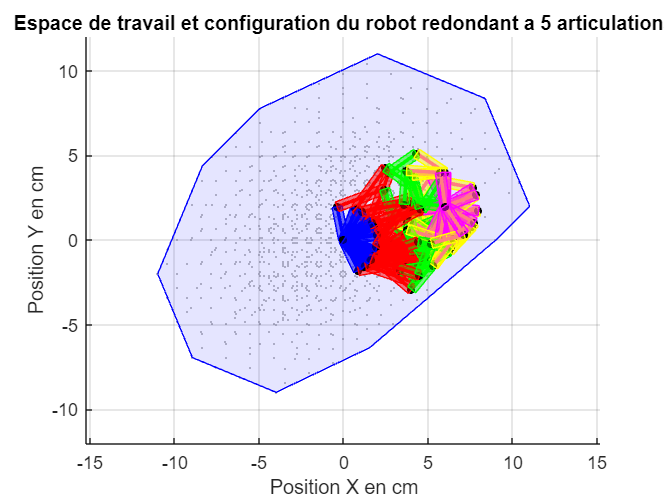

% Définir les couleurs pour chaque type de segment
color_segment_OA = 'b'; % Segment OA
color_segment_AB = 'r'; % Segment AB
color_segment_BC = 'g'; % Segment BC
color_segment_CD = 'm'; % Segment CD
color_segment_DE = 'y'; % Segment DE

% Visualisation des configurations du robot
for i = 1:size(all_solutions, 1)
    % Extraire les angles d'articulation pour cette configuration
    theta1 = all_solutions(i, 1);
    theta2 = all_solutions(i, 2);
    theta3 = all_solutions(i, 3);
    theta4 = all_solutions(i, 4);
    theta5 = all_solutions(i, 5);

    % Calcul des positions des articulations du robot avec les valeurs des angles d'articulation calculées
    O = [0, 0]; % Position de l'origine
    A = [a1*cos(theta1), a1*sin(theta1)]; % Position de l'articulation A
    B = A + [a2*cos(theta1+theta2), a2*sin(theta1+theta2)]; % Position de l'articulation B
    C = B + [a3*cos(theta1+theta2+theta3), a3*sin(theta1+theta2+theta3)]; % Position de l'articulation C (extrémité de l'effecteur)
    D = C + [a4*cos(theta1+theta2+theta3+theta4), a4*sin(theta1+theta2+theta3+theta4)]; % Position de l'articulation C (extrémité de l'effecteur)
    E = D + [a5*cos(theta1+theta2+theta3+theta4+theta5), a5*sin(theta1+theta2+theta3+theta4+theta5)]; % Position de l'articulation C (extrémité de l'effecteur)

    % Tracer le robot pour cette configuration 
    plot([O(1), A(1)], [O(2), A(2)], 'LineWidth', 2, 'Color', color_segment_OA, 'DisplayName', ['Segment OA - Solution ', num2str(i)]); % Segment OA
    plot([A(1), B(1)], [A(2), B(2)], 'LineWidth', 2, 'Color', color_segment_AB, 'DisplayName', ['Segment AB - Solution ', num2str(i)]); % Segment AB
    plot([B(1), C(1)], [B(2), C(2)], 'LineWidth', 2, 'Color', color_segment_BC, 'DisplayName', ['Segment BC - Solution ', num2str(i)]); % Segment BC
    plot([C(1), D(1)], [C(2), D(2)], 'LineWidth', 2, 'Color', color_segment_CD, 'DisplayName', ['Segment CD - Solution ', num2str(i)]); % Segment BC
    plot([D(1), E(1)], [D(2), E(2)], 'LineWidth', 2, 'Color', color_segment_DE, 'DisplayName', ['Segment DE - Solution ', num2str(i)]); % Segment BC
    scatter([O(1), A(1), B(1), C(1), D(1), E(1)], [O(2), A(2), B(2), C(2), D(2), E(2)], 20, 'k', 'filled', 'DisplayName', ['Articulations - Solution ', num2str(i)]); % Marques pour les articulations

    % Ajouter des rectangles autour des segments
    rectWidth = 0.3; % Ajustez cette valeur selon vos besoins
    drawSegmentRectangle(O, A, rectWidth, 'b');
    drawSegmentRectangle(A, B, rectWidth, 'r');
    drawSegmentRectangle(B, C, rectWidth, 'g');
    drawSegmentRectangle(C, D, rectWidth, 'y');
    drawSegmentRectangle(D, E, rectWidth, 'm');
  
end 


% Calculer les limites des axes
xlim([-12, 12]); 
ylim([-12, 12]);
axis equal

% Configurer le titre et les étiquettes des axes
title('Espace de travail et configuration du robot redondant a 5 articulations');
xlabel('Position X en cm');
ylabel('Position Y en cm');


% Affichage de la grille
grid on;

hold off; 

### Fonctions

% Fonction cinematique inverse et pour créer un rectangle autour d'un segment

function drawSegmentRectangle(startPoint, endPoint, rectWidth, color)
    % Calcule la longueur et l'angle du segment
    segmentLength = norm(endPoint - startPoint);
    segmentAngle = atan2(endPoint(2) - startPoint(2), endPoint(1) - startPoint(1));
    
    % Calcule les coordonnées des coins du rectangle
    dx = rectWidth * cos(segmentAngle + pi/2);
    dy = rectWidth * sin(segmentAngle + pi/2);
    rectPoints = [startPoint(1) - dx, startPoint(2) - dy;
                  startPoint(1) + dx, startPoint(2) + dy;
                  endPoint(1) + dx, endPoint(2) + dy;
                  endPoint(1) - dx, endPoint(2) - dy;
                  startPoint(1) - dx, startPoint(2) - dy];
    
    % Trace le rectangle
    fill(rectPoints(:, 1), rectPoints(:, 2), color, 'EdgeColor', color, 'FaceAlpha', 0.5);
end

function [all_solutions] = find_inverse_kinematics(a1, a2, a3, a4, a5, x_desired, y_desired, num_configurations, min_angle, max_angle)
    % Définir les angles d'articulation
    syms theta1 theta2 theta3 theta4 theta5;

    % Définir une tolérance et un nombre maximum d'itérations
    tolerance = 0.0000001;
    max_iterations = 100;

    % Initialiser une liste pour stocker les configurations atteignables
    all_solutions = [];

    % Recherche des configurations
    while size(all_solutions, 1) < num_configurations
        % Initialiser les angles d'articulation
        theta1 = min_angle(1) + rand * (max_angle(1) - min_angle(1));
        theta2 = min_angle(2) + rand * (max_angle(2) - min_angle(2));
        theta3 = min_angle(3) + rand * (max_angle(3) - min_angle(3));
        theta4 = min_angle(4) + rand * (max_angle(4) - min_angle(4));
        theta5 = min_angle(5) + rand * (max_angle(5) - min_angle(5));


        % Boucle d'itération pour trouver les angles d'articulation
        for i = 1:max_iterations
            % Calculer les équations directes de cinématique directe
            x = a1*cos(theta1) + a3*cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - a3*sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + a2*cos(theta1)*cos(theta2) - a2*sin(theta1)*sin(theta2) + a5*cos(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)))) + a4*cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - a5*sin(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))) + sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)))) - a4*sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)));
            y = a1*sin(theta1) + a3*cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + a3*sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) + a2*cos(theta1)*sin(theta2) + a2*cos(theta2)*sin(theta1) + a5*cos(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))) + sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)))) + a4*cos(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))) + a5*sin(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)))) + a4*sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)));
          
            % Calculer l'erreur de position
            error_x = x_desired - x;
            error_y = y_desired - y;
            error = [error_x; error_y];

            % Calculer les dérivées partielles
            dx_dtheta1 = -a1*sin(theta1) - a3*cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - a3*sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) - a2*sin(theta1)*sin(theta2) - a2*cos(theta1)*cos(theta2) - a4*sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - a5*sin(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))));
            dx_dtheta2 = -a3*cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - a3*sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + a2*cos(theta1)*cos(theta2) - a2*sin(theta1)*sin(theta2) - a4*sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - a5*sin(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))));
            dx_dtheta3 = a3*sin(theta3)*(sin(theta1)*sin(theta2) - cos(theta1)*cos(theta2)) + a4*sin(theta4)*(sin(theta1)*sin(theta2) - cos(theta1)*cos(theta2)) + a5*sin(theta5)*(sin(theta1)*sin(theta2) - cos(theta1)*cos(theta2));
            dx_dtheta4 = -a4*sin(theta4)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - a5*sin(theta5)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2));
            dx_dtheta5 = -a5*sin(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))) + a5*cos(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))) - sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)))));
    
            dy_dtheta1 = a1*cos(theta1) + a3*cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + a3*sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) + a2*cos(theta2)*sin(theta1) + a2*cos(theta1)*sin(theta2) + a4*cos(theta4)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) + a5*cos(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))) + sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)))) + a5*sin(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))));
            dy_dtheta2 = a3*cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + a3*sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - a2*sin(theta1)*sin(theta2) - a2*cos(theta1)*cos(theta2) - a4*sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - a5*sin(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))));
            dy_dtheta3 = - a3*sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + a4*sin(theta4)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + a5*sin(theta5)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1));
            dy_dtheta4 = - a4*sin(theta4)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) - a5*sin(theta5)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1));
            dy_dtheta5 = a5*cos(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))) - sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - a5*sin(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) + sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)))));
    
            % Construire la Jacobienne
            J = [dx_dtheta1, dx_dtheta2, dx_dtheta3, dx_dtheta4, dx_dtheta5; 
             dy_dtheta1, dy_dtheta2, dy_dtheta3, dy_dtheta4, dy_dtheta5];
    
            % Vérifier la convergence
            if norm(error) < tolerance
                %disp('Convergence atteinte.');
                % Stocker la solution
                all_solutions = [all_solutions; [theta1, theta2, theta3, theta4, theta5, x, y]];
                
                break;
            end

            % Calculer la variation des angles d'articulation
            delta_theta = pinv(J) * error;
    
            % Mise a jour des les angles d'articulation
            theta1 = theta1 + delta_theta(1);
            theta2 = theta2 + delta_theta(2);
            theta3 = theta3 + delta_theta(3);
            theta4 = theta4 + delta_theta(4);
            theta5 = theta5 + delta_theta(5);

            % Maintien des angles entre 0 et 2*pi
            theta1 = mod(theta1, 2*pi);
            theta2 = mod(theta2, 2*pi);
            theta3 = mod(theta3, 2*pi);
            theta4 = mod(theta4, 2*pi);
            theta5 = mod(theta5, 2*pi);
        end
    end
     % Afficher toutes les configurations trouvées en radian
    disp('Configurations possibles du robot pour la position désirée :');
    disp('    Theta1   Theta2    Theta3    Theta4    Theta5  X_calculé   Y_calculé');
    disp(all_solutions);  
    
    % Convertion des angles de radians en degrés et afficher les résultats
    all_solutions_deg = rad2deg(all_solutions(:, 1:5));
    % Afficher toutes les configurations trouvées en degrrs
    % disp('Configurations possibles du robot pour la position désirée :');
    % disp('    Theta1°   Theta2°   Theta3°   Theta4°  Theta5°   X_calculé   Y_calculé')
    % disp([all_solutions_deg, all_solutions(:, 6:7)]);
   
end